clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["0", "4", "7", "8", "A", "D", "H"];
categories = ["0", "4", "7", "8", "A", "D", "H"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    pngFiles = dir(fullfile(folderPath, "*.png"));

    for j = 1:length(pngFiles)
        pngFilePath = fullfile(folderPath, pngFiles(j).name);
        image = imread(pngFilePath);
        allData = [allData; {image, categories(i)}];
    end
end

% convert images to features
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
features = zeros(numImages, prod(imageSize));

for i = 1:numImages
    image = allData.Image{i};
    features(i, :) = image(:)';
end

labels = categorical(allData.Label);

% split data into training and test set
cv = cvpartition(labels, 'HoldOut', 0.25);
idx = cv.test;
trainIdx = training(cv);
testIdx = test(cv);
trainFeatures = features(trainIdx, :);
trainLabels = labels(trainIdx, :);
testFeatures = features(testIdx, :);
testLabels = labels(testIdx, :);

% Train an SVM classifier
svmTemplate1 = templateSVM('KernelFunction', 'linear');
svmClassifier1 = fitcecoc(trainFeatures, trainLabels, 'Learners', svmTemplate1);

svmTemplate2 = templateSVM('KernelFunction', 'gaussian',"Type","classification");
svmClassifier2 = fitcecoc(trainFeatures, trainLabels, 'Learners', svmTemplate2);

% Predict labels for the test set
predictedLabels1 = predict(svmClassifier1, testFeatures);

% Evaluate the classifier's performance
confusionMatrix1 = confusionmat(testLabels, predictedLabels1);
accuracy1 = sum(diag(confusionMatrix1)) / sum(confusionMatrix1(:));

fprintf('Accuracy: %.2f%%\n', accuracy1 * 100);

Accuracy: 90.99%



% Predict labels for the test set
predictedLabels2 = predict(svmClassifier2, testFeatures);

% Evaluate the classifier's performance
confusionMatrix2 = confusionmat(testLabels, predictedLabels2);
accuracy2 = sum(diag(confusionMatrix2)) / sum(confusionMatrix2(:));

fprintf('Accuracy: %.2f%%\n', accuracy2 * 100);

Accuracy: 29.05%


% Plot the results
figure;
kernel = ["Linear", "Gaussian"];
AccuracyResults = [accuracy1 accuracy2];
bar(kernel, AccuracyResults)
xlabel('Kernel')
ylabel('Accuracy')
ylim([0, 1]); 
title('Accuracy Performance vs Kernel')
grid on;

% Save the plot as an EPS file
eps_filename = 'results/svm.eps'

eps_filename = 'results/svm.eps'

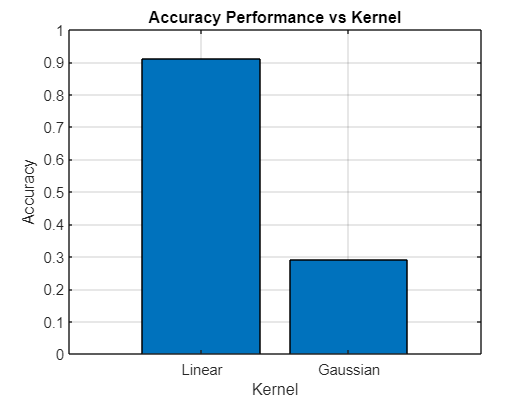

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/svm.eps


% Calculate precision, recall, and F1-score
confusionMatrix = confusionmat(testLabels, predictedLabels)

truePositive = confusionMatrix(1, 1);
falsePositive = confusionMatrix(2, 1);
falseNegative = confusionMatrix(1, 2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);
fprintf('Recall: %.2f\n', recall);
fprintf('F1-Score: %.2f\n', f1Score);
% Visualize the confusion matrix using imagesc and annotate precision
figure;
imagesc(confusionMatrix);
colorbar;
colormap('jet'); % You can change the colormap as needed
title('Confusion Matrix');
xlabel('Predicted');
ylabel('Actual');
xticks(1:numel(categories));
xticklabels(categories);
yticks(1:numel(categories));
yticklabels(categories);

% Calculate and annotate precision for each class
for i = 1:numel(categories)
    for j = 1:numel(categories)
        precision = confusionMatrix(i, i) / sum(confusionMatrix(:, i));
       text(j, i, sprintf('%.2f', precision), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'k', 'FontWeight', 'bold');
    end
end